# Question 2

clear, clc
close all

## section a - Taylor Series

syms x y real
f = sin(x)*log(x*y)

$$f = \log\left(x\,y\right)\,\sin\left(x\right)$$

a = [1;1];
% denote X
X =[x;y];

% 1st polynomial
f_sub=subs(f,X,a); % aux calc
grad_f = subs(gradient(f),X,a); % aux calc

T1 = collect(f_sub + (X-a).' * grad_f,X)

$$T1 = \sin\left(1\right)\,x+\sin\left(1\right)\,y-2\,\sin\left(1\right)$$

% 2nd polynomial:
hess_f = hessian(f); % aux calc

T2 = collect(T1 + (1/2) * (X-a).' * subs(hess_f,X,a) * (X-a),X)

$$T2 = \left(\cos\left(1\right)-\frac{\sin\left(1\right)}{2}\right)\,x^{2}+\cos\left(1\right)\,x\,y+\left(2\,\sin\left(1\right)-3\,\cos\left(1\right)\right)\,x+\left(-\frac{\sin\left(1\right)}{2}\right)\,y^{2}+\left(2\,\sin\left(1\right)-\cos\left(1\right)\right)\,y+2\,\cos\left(1\right)-3\,\sin\left(1\right)$$

% 3rd polynomial:
f_xxx = subs(diff(hess_f(1,1),x),X,a); % aux calc
f_yyy = subs(diff(hess_f(2,2),y),X,a); % aux calc
f_xxy = subs(diff(hess_f(1,1),y),X,a); % aux calc
f_xyy = subs(diff(hess_f(2,1),y),X,a); % aux calc

T3 = collect(T2 + (1/6) * (3 * (x-a(1))^2 * (y-a(2)) * f_xxy + 3 * (x-a(1)) * (y-a(2))^2 * f_xyy + (x-a(1))^3 * f_xxx + (y-a(2))^3 * f_yyy) , X)

$$T3 = \left(-\frac{\cos\left(1\right)}{2}-\frac{\sin\left(1\right)}{6}\right)\,x^{3}+\left(-\frac{\sin\left(1\right)}{2}\right)\,x^{2}\,y+\left(\frac{5\,\cos\left(1\right)}{2}+\frac{\sin\left(1\right)}{2}\right)\,x^{2}+\left(-\frac{\cos\left(1\right)}{2}\right)\,x\,y^{2}+\left(2\,\cos\left(1\right)+\sin\left(1\right)\right)\,x\,y+\left(\frac{\sin\left(1\right)}{2}-5\,\cos\left(1\right)\right)\,x+\frac{\sin\left(1\right)}{3}\,y^{3}+\left(\frac{\cos\left(1\right)}{2}-\frac{3\,\sin\left(1\right)}{2}\right)\,y^{2}+\left(\frac{5\,\sin\left(1\right)}{2}-2\,\cos\left(1\right)\right)\,y+3\,\cos\left(1\right)-\frac{8\,\sin\left(1\right)}{3}$$

% for testing:
% T = collect(expand(taylor(f,[x y],[1 1],'Order',4)),X) % For comparsion

## section b - plot

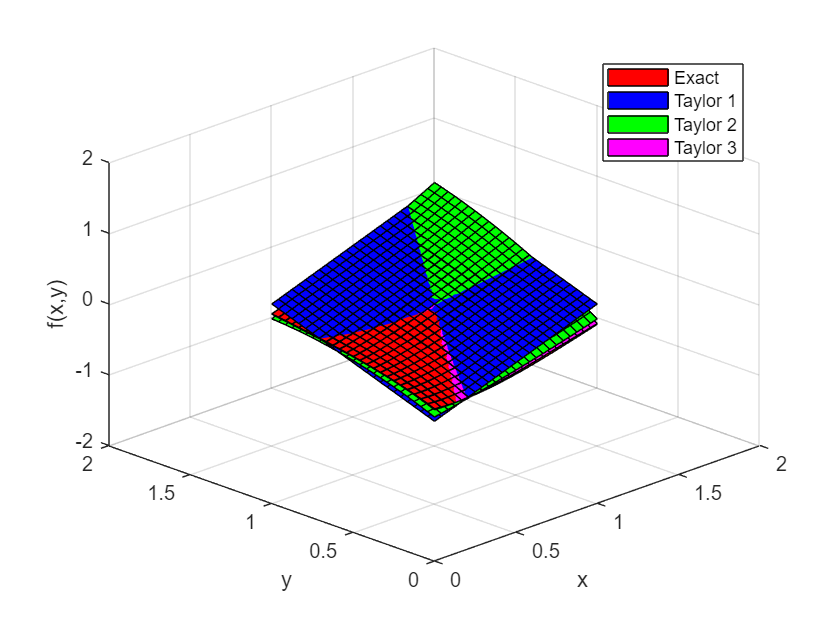

% find solution: step 1: transfer to matlab function.
T3_mF = matlabFunction(T3);
T2_mF = matlabFunction(T2);
T1_mF = matlabFunction(T1);
f_mF = matlabFunction(f);
vec = linspace(0.5,1.5,25);
[x_grid,y_grid]=meshgrid(vec,vec);
% step 2 - substitute
z_T3 = T3_mF(x_grid,y_grid);
z_T2 = T2_mF(x_grid,y_grid);
z_T1 = T1_mF(x_grid,y_grid);
z_real = f_mF(x_grid,y_grid);
% plot
close all
hold on
p1=surface(x_grid,y_grid,z_real,'FaceColor','red');
p1.DisplayName = 'Exact';
p2=surface(x_grid,y_grid,z_T1,'FaceColor','blue');
p2.DisplayName = 'Taylor 1';
p3=surface(x_grid,y_grid,z_T2,'FaceColor','green');
p3.DisplayName = 'Taylor 2';
p4=surface(x_grid,y_grid,z_T3,'FaceColor','magenta');
p4.DisplayName = 'Taylor 3';
view(-45,30)
zlim([-2 2]);xlim([0 2]);ylim([0 2])
xticks(0:0.5:2);yticks(0:0.5:2)
xlabel('x');ylabel('y');zlabel('f(x,y)')
grid on
legend('Location','northeast')
hold off